## Week 6 - Part 1

Dave Hill - Oregon State University

So, with this week, we are going to pivot away from basic matlab building blocks (programming structures, file i/o, etc.) and towards some common analysis tasks having to do with environmental and engineering data. One very common task is that of **parameter estimation** and/or **curve fitting**. In other words, we have some data, and we have some mathematical model for that data. And, we need to determine the best suite of model parameters, i.e., the parameters that will give our model the *best fit* to the data.

To ease our introduction into this topic, we will start with a very simple model...the equation of a straight line. For this easy task, Matlab has a lot of easy tools that we can use. But, as we move towards more and more complex models, the tools available to us in Matlab will be increasingly complex to use.


clear all
close all
clc

## Fitting a Straight Line

Let's take a quick look at some data and let's fit a straight line to it. A straight line is a 'two parameter' model. There is a slope and an intercept. So, let us create some data that looks like a straight line, but has some noise in it.

x=0:1:10;
m=0.5; %slope
b=1; %intercept

%create data, adding in some noise
yo=m*x+b+2*(rand(size(x))-0.5);

figure(1)
plot(x,yo,'o');
axis([0 10 0 6]);

Ok, nice. So, now if I ask you to fit a straight line to this, how do you do it? Do you simply 'eyeball' it? 

Once you 'run' this section, try experimenting with the sliders below. Look at how the figure changes. Adjust the sliders until you get the 'best' fit according to your eye.

close all
%set the slope
slope = 0.45 
%set the intercept
intercept = 0.7
%let's plot the result.
plot(x,yo,'o');
axis([0 10 0 6]);
hold on
plot(x,x*slope+intercept,'r')

### Solution with Polyfit

Ok, so that's pretty cool. But, having to 'eyeball' things is not really accurate. So, we can fit a straight line incredibly quickly with polyfit. Polyfit will return the fit parameters, and we can use these along with polyval to compute the y data corresponding to the straight line fit.

close all
figure(3)
plot(x,yo,'o'); %plot the original data.
axis([0 10 0 6]);

%matlab best fit
P=polyfit(x,yo,1)
hold on
%plot YOUR best fit (from sliders above)
plot(x,x*slope+intercept,'r')
%plot matlab best fit
plot(x,polyval(P,x),'g')
legend('original data','eyeball fit','BEST fit')
title(['Best fit parameters: m = ' num2str(P(1)) ', b = ' num2str(P(2))])

### Minimizing Residual Errors

But, what in the world is going on?? How does Matlab do this? Well, it has to do with minimizing the square error of the model fit. Consider this. We have N observed data values...


$$y_{o1}, y_{o2}, \ldots, y_{oN}$$


Now, we create a model, and we will have N model estimates of our data


$$y_{m1}, y_{m2}, \ldots, y_{mN}$$


We define the `residual error' between the estimates and the observations as


$$S=\sum_{i=1}^{N}(y_{o}-y_{m})^{2}$$


And, in the case of a straight line, where our proposed model is $y_{m}=mx+b$, our error is


$$S=\sum_{i=1}^{N}(y_{o}-mx-b)^{2}$$


So, now the goal of a 'good' curve fit is to minimze this error, right! It'll never be zero, but we need to make it as small as possible. To minimize something, we take it's derivative and set it to zero. So, let us differentiate with respect to the slope m and set the result equal to zero.


$$\frac{\partial S}{\partial m}=\sum 2(y_{o}-mx-b)\frac{\partial}{\partial x}(y_{o}-mx -b)=0$$


This becomes


$$\sum 2(y_{o}-mx-b)(-x)=0$$


Or, even simpler:


$$0=\sum y_{o}x - \sum mx^{2}-\sum bx$$


If we do the same thing, but differentiate the error with respect to the other model parameter, the intercept b, we get


$$0=\sum y_{o} - \sum mx-\sum b$$


Now, this is pure linear algebra. We can express this in a matrix form as


$$\pmatrix{\sum x^{2} & \sum x \cr \sum x & N} \pmatrix{m \cr b}=\pmatrix{\sum y_{o}x \cr \sum y_{0}}
$$


And, Matlab is brilliant at doing matrix solutions. Let's try this with the code below.

### Minimizing Residual Errors Example

close all
figure(4)
plot(x,yo,'o'); %original data
axis([0 10 0 6]);
hold on

%matlab best fit from polyfit
plot(x,polyval(P,x),'g')

%try least squares...let us build up the matrix A (left matrix in the above
%section)
A(1,1)=sum(x.*x);
A(2,1)=sum(x);
A(1,2)=sum(x);
A(2,2)=length(x);
%next, let us build up the vector B (the column vector on the right hand
%side of the equation above
B(1,1)=sum(yo.*x);
B(2,1)=sum(yo);

%solving this is as easy as the next line!
soln=A\B;
%let us pull out the values of m and b, and plot the result...
mlsq=soln(1);
blsq=soln(2);
ylsq=mlsq*x+blsq;
plot(x,ylsq,'kx')

legend('Raw Data','Matlab Fit','Least Squares')

You can see that the least squares approach that we took is EXACTLY the same as Matlab's polyfit. This is how curve fitting is done!

## Beyond Straight Lines

Ok, well with Matlab we can do more that fit straight lines. Below is an illustration of using polyfit

clear all
close all

%lets create a quadratic (parabola) and then add some noise.
intercept = 0.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data, i.e. the x values
noiseAmp = 0.5;         % for random number noise

%create the actual data...i.e., the y values
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));
figure(5)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')

%Let's fit a quadratic to this with polyval. Note the ,2 (3rd argument of
%function). That is how we specify a 2nd order polynomial
p=polyfit(x,yData,2);   %try a quadratic.

%plot this
hold on
%compute the model estimate (the quadratic curve fit) from the parameters
yEst=polyval(p,x);
plot(x,yEst,'r')

%what happens if we guess the model poorly? Try linear fit
p2=polyfit(x,yData,1);  %linear
yEstlinear=polyval(p2,x);
plot(x,yEstlinear,'g')
legend('Data','Quad fit','Lin fit')

So, you can see that it is up to US to figure out what a good model to try is...linear, quadratic, exponential, etc. By the way, we can access all sorts of useful information on the fit by using more variables on the left hand side of the polyfit call.

%you can get information on how good the fit is.
[p2,S]=polyfit(x,yData,1);
S
S.normr    %this is the root mean square error, which is a measure of the goodness of fit.
[p3,S]=polyfit(x,yData,2);
S    %note the lower root mean square error in this case (the quadratic)

## Beyond Polyfit - the FIT function

So, polyfit is super cool. But it only works for polynomial fits. What if you think your data follows a different type of behaviour? What if it is exponential? Or, logarithmic? Or, seems to be described by some other mathematical function? Well, with the fit function, you can fit the data to whatever functional form you want! Let us illustrate this with some data that follows a quadratic:

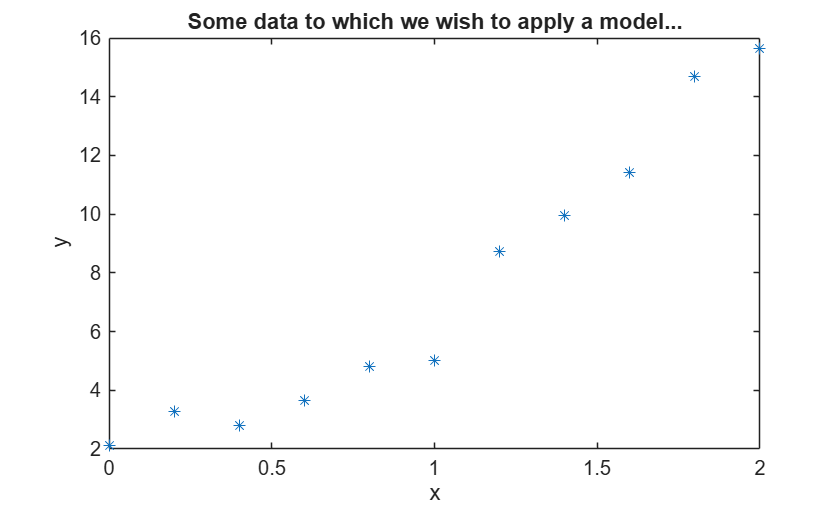

clear all
close all

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2]';        % independent data
noiseAmp = 0.5;         % for random number noise

%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));
figure(6)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')
hold on

Now, I am going to use the fit function. If you type 'help fit' at the command prompt, you can see that there are many options for you to select from. We could just choose a second order polynomial again:

%let's again try a polynomial (quadratic) fit
F0= fit(x',yData','poly2')   %this is how we choose quad fit

Error using fit>iFit (line 56)
X must be a matrix with one or two columns.

Error in fit (line 37)
[fitobj, goodness, output, convmsg] = iFit( xdatain, ydatain, fittypeobj, ...

%you will see information written to the screen on the coefficients and
%confidence intervals on those coefficients.

%plot results
plot(x,F0(x),'r')    %F0 is now like a function

Now, this is getting a bit outside the scope of this class (take a stats class!), but because of the noise in our data, our 'fit' is uncertain. We can consider the 95% confidence bounds and plot a result where we show the 'envelope' of results, due to our uncertainty.

%With the confidence intervals we can plot confidence bounds.
p11=predint(F0,x,0.95,'observation','off');
figure(2)
plot(F0,x,yData);
hold on
plot(x,p11,'m--')
legend off
title('Example of curve fitting with fit function')

What if we wanted a different proposed model fit? One not given as an option with the fit function? As an example, say we wanted to force our quadratic model to go through the origin? This essentially eliminates the 'constant' term in a polynomial fit. Well, we can create a custom fit type

ft=fittype( @(a,b,x) a*x.^2+b*x); %note that there is no intercept in this proposed model (well...it is 0).
F1=fit(x,yData,ft)  %you may need to help by supplying guess for starting point
                    %for parameter values...
                    
figure(3); hold off
plot(x,yData,'*'); hold on
plot(F1,'r')  %note we are not plottin x vs y; we are plotting a 'fit' variable type
title('Curve fitting with a custom polynomial model fit')

## Fundamental Least Squares Search, i.e. the Sledgehammer...

Ok, so, there is another way to go about things. We can take a 'brute force' approach for manually searching all of parameter space to find the parameters that give the best fit. This is not very elegant. But, sometimes, this approach may be necessary. Let us again illustrate this by generating some noisy quadratic data.

clear all
close all

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data
noiseAmp = 0.4;         % for random number noise
%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));

### Constant

Lets first try a model of y = m(0), just a mean.  Obviously this is a poor model choice, but it allows us to illustrate a point. We will find the estimate by trying a suite of possible values

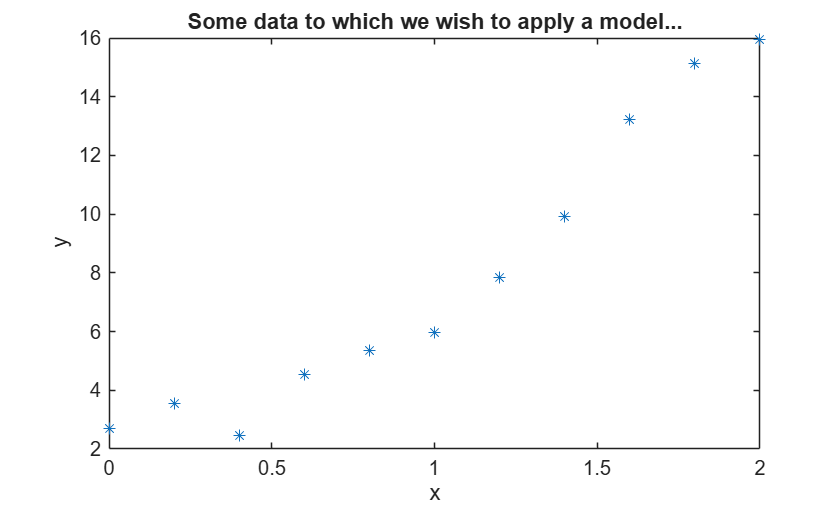

%specify range of values
m0 = [0: 0.01: 10.0];
for j = 1: length(m0)
    yPred = repmat(m0(j), size(x)); %this just creates a vector having m0(j) values (the constant value)
    e2(j) = sum((yData - yPred).^2); %we are computing the sum of squared errors
end

figure(1)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')

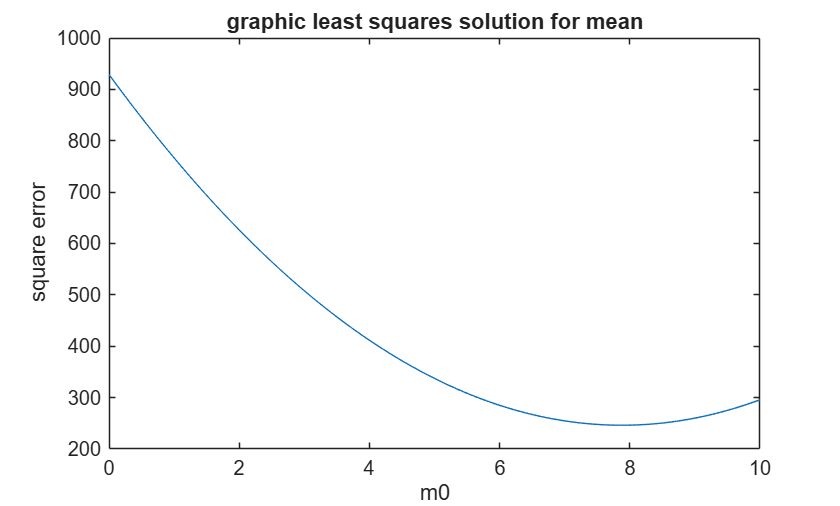

%find our best fit
figure(2)
plot(m0, e2)
xlabel('m0')
ylabel('square error')
title('graphic least squares solution for mean')


[e2min, k] = min(e2);   % look for minimum
m0Est = m0(k)

m0Est = 7.8800

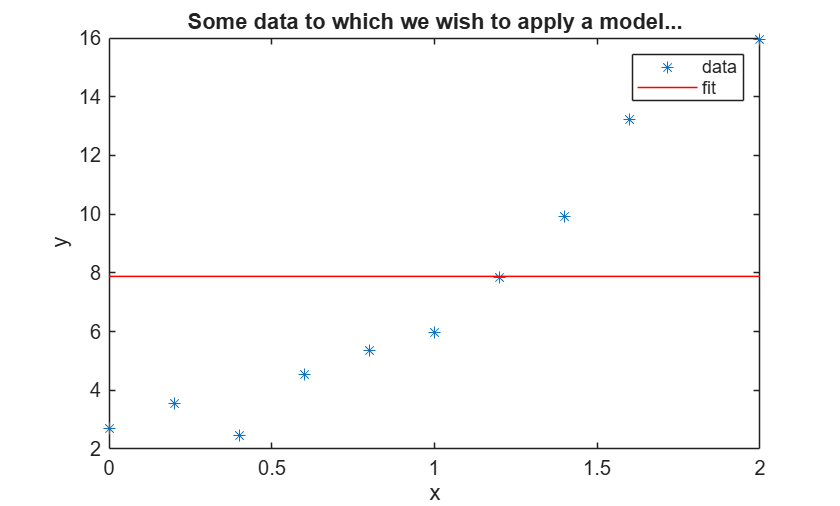

figure(1)
hold on
plot([x(1) x(end)],[m0Est m0Est],'r')
legend('data','fit')

### Linear

Now try looking for the minimum square error using a model that has an intercept and trend (linear fit to data). So, this is a two-parameter model fit! We must search 2d parameter space to find the smallest error...

clear e2
m0 = [0: 0.01: 10.0];    
m1 = [0: 0.01: 10.0];

for j = 1: length(m0)
    for k = 1: length(m1)
        yPred = repmat(m0(j), size(x)) + m1(k)*x;
        e2(j, k) = sum((yData - yPred).^2); %compute the square error
    end
end

figure(3); hold off
pcolor(m1, m0, e2); shading flat
xlabel('m1')
ylabel('m0')
title('sum of square error')
colorbar

[val, ind] = min(e2(:));    % find minimum error
[r,c] = ind2sub(size(e2), ind);  % express as row and column
m0Estnew = m0(r)

m0Estnew = 0.7000

m1Est = m1(c)

m1Est = 7.1800

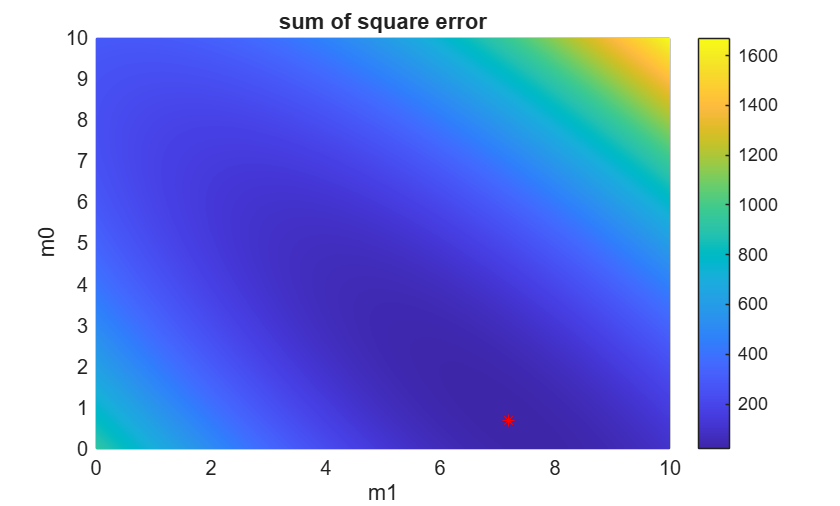

hold on
plot(m1Est, m0Estnew, 'r*')

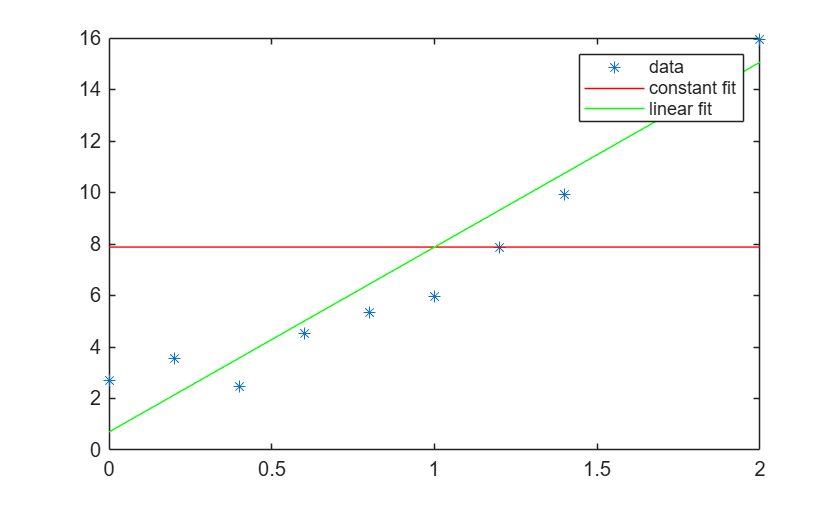


figure(4); hold off
plot(x,yData,'*'); hold on
plot([0 2],[m0Est m0Est],'r') %adds the 'mean value' fit
plot(x,polyval([m1Est m0Estnew],x),'g')
legend('data','constant fit','linear fit')

Note that the same thing could be done for a quadratic fit, or really any other function.  This is tedious and requires us to do a lot of wasted calculations.  It would be much better if we could make a first guess, then intelligently search downslope in error space to find the minimum.  This is exactly what is done on a number of routines including nlinfit in matlab (next method).

## Optimization Functions - nlinfit

% This is one of a great many functions in
% matlab that are really 'optimization' functions. What are we trying to
% optimize? Well, we are really trying to minimize the error between the
% data and the model fit.

clear all
close all
clc

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data
noiseAmp = 1.4;         % for random number noise
%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));

%define the model function. Here I use anonymous function. You can do this
%with a separately saved function file as well.
QUAD=@(C,x) C(1)*x.^2+C(2)*x+C(3) 

QUAD = function_handle with value:
    @(C,x)C(1)*x.^2+C(2)*x+C(3)


[beta,R,JCOVB,MSE] = nlinfit(x, yData, QUAD, [100 100 100]); %note the need to supply initial guesses
beta %display output coefficients

beta =     3.4640   -0.8128    4.6639


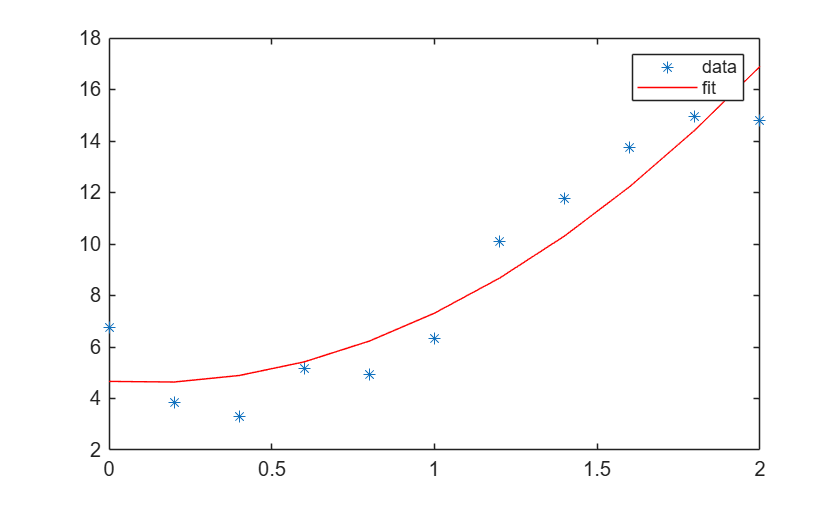

figure(1)
plot(x,yData,'*')
hold on
plot(x,QUAD(beta,x),'r') %add model fit to the plot
legend('data','fit')


% for a pile for functions to do least squares and constrained
% fitting, look at the optim toolbox in matlab (lsqcurvefit or lsqnonlin)

## Regression Techniques

The methods above are good when something is known about the expected behavior or the functional form of the model. This knowledge can come from what you about the partial physics of the problem at hand. Or, it can come from your 'best guess' of the functional form, e.g. 'that looks like a logarithmic relationship.' So, there ends up being an equation involved.

Other methods focus more on modeling the statistical relationship between variables. The dependent variable is called the response variable, and it will depend on any number of independent variables called predictor variables. In Matlab, there are a great many tools for you to explore including

- fitlm

- regress

- stepwiselm

### Fitlm Example

Let us load some data on cars (MPG, weight, horsepower, and more) and look at the data

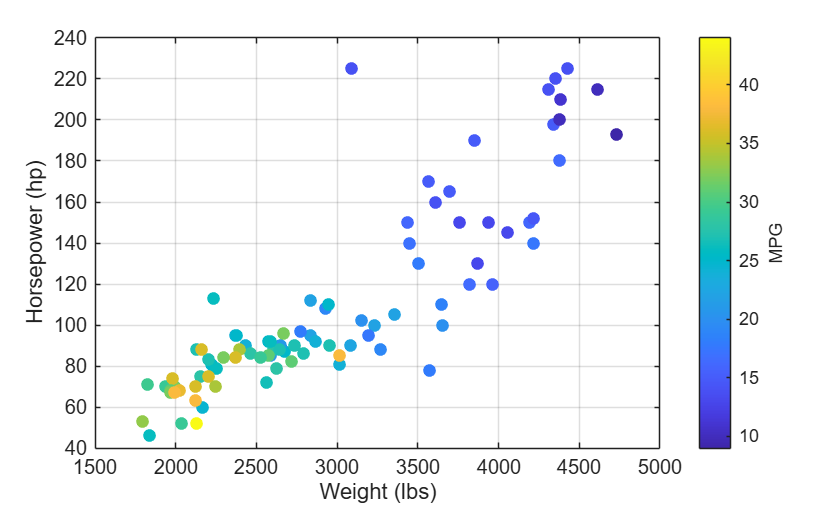

clear all
close all
load carsmall
figure(1)
scatter(Weight,Horsepower,40,MPG,'filled'); xlabel('Weight (lbs)'); ylabel('Horsepower (hp)'); box on; grid on;
c=colorbar; c.Label.String=('MPG');

Ok, so it looks like MPG is better for light cars with small horsepower engines. No surprise there. Can we dig into this relationship? An easy way to so this is with tables and with the FITLM function, so let's try that.

tbl = table(Weight, Horsepower, MPG); % focus on weight and horsepower being the most important

% Fit a multiple linear regression model: MPG ~ Weight + Acceleration
mdl = fitlm(tbl, 'MPG ~ Weight + Horsepower');

% Display the model summary
disp(mdl);


Linear regression model:
    MPG ~ 1 + Weight + Horsepower

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        47.769       1.7417     27.427     1.751e-45
    Weight         -0.0065651    0.0010507    -6.2484    1.3519e-08
    Horsepower      -0.042018     0.018671    -2.2504       0.02686


Number of observations: 93, Error degrees of freedom: 90
Root Mean Squared Error: 4.07
R-squared: 0.752,  Adjusted R-Squared: 0.747
F-statistic vs. constant model: 136, p-value = 5.57e-28


Now, when you do linear regression, you are basicall saying something like:


$$y = A + B_{1}X_{1}+B_{2}X_{2}$$


So, when we display the model we are more or less seeing the constant and then the coefficients that multiply the various predictor variables. In this case, the negative signs indicate that MPG goes down with increasing HP and weight. 

Now that we have built the model we can use it to predict MPG values for any new combinations of our predictor variables. Let's do this over a large range of values.

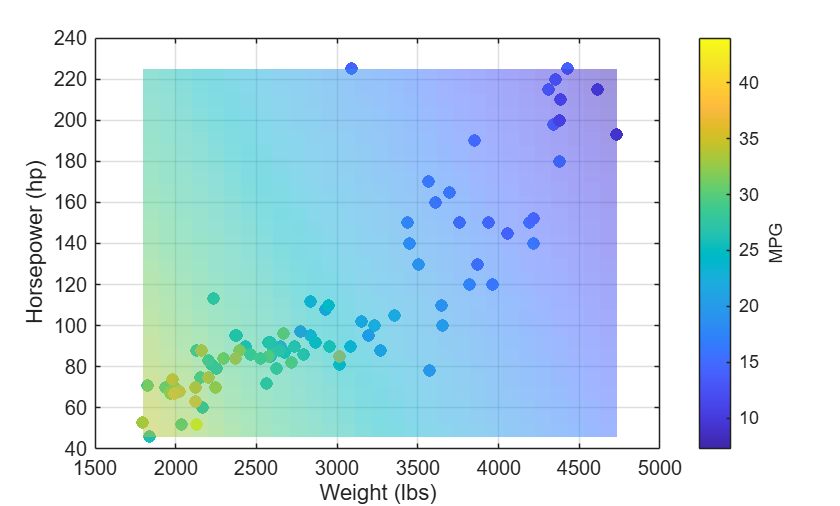

figure;
scatter(Weight,Horsepower,40,MPG,'filled'); xlabel('Weight (lbs)'); ylabel('Horsepower (hp)'); box on; grid on;
c=colorbar; c.Label.String=('MPG'); hold on

% Create a grid over Weight and Horsepower to generate the surface
[WeightGrid, HorsepowerGrid] = meshgrid(...
    linspace(min(tbl.Weight), max(tbl.Weight), 30), ...
    linspace(min(tbl.Horsepower), max(tbl.Horsepower), 30));

% Predict MPG values over the grid using the fitted model
MPGGrid = predict(mdl, table(WeightGrid(:), HorsepowerGrid(:), 'VariableNames', {'Weight', 'Horsepower'}));
MPGGrid = reshape(MPGGrid, size(WeightGrid));

% Draw the regression surface
surf(WeightGrid, HorsepowerGrid, MPGGrid, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

### Stepwiselm Example

So, linear regression can be a powerful tool, but what if you don't know, up front, what your list of predictor variables should be? In the example above, we have a lot of candidates. There are automated tools such as stepwiselm that will go in and 'add in and take out' various predictors with the goal of coming up with the 'best' set. Let's go back to the small car dataset and try it out. If you look carefully, you should see that the Rsquared of this results is slightly better than before, so there is value in letting Matlab try out all the combinations for you!

clear all
close all
% 1. Load the sample car data
load carsmall
tbl = table(Acceleration, Displacement, Horsepower, Weight, Cylinders, MPG); %note that we had include many more options this time...

% 4. Run the stepwise linear regression
% We start from a 'constant' model (intercept only) and let MATLAB 
% add or remove terms dynamically based on p-values.
mdl = stepwiselm(tbl, 'constant', 'ResponseVar', 'MPG')

1. Adding Weight, FStat = 259.3087, pValue = 1.643351e-28
2. Adding Cylinders, FStat = 9.3065, pValue = 0.0029916
3. Adding Weight:Cylinders, FStat = 4.1419, pValue = 0.044774


mdl = Linear regression model:
    MPG ~ 1 + Weight*Cylinders

Estimated Coefficients:
                         Estimate         SE         tStat       pValue  
                        __________    __________    _______    __________

    (Intercept)              64.34        7.7394     8.3133    9.1867e-13
    Weight               -0.010856     0.0027735    -3.9141     0.0001761
    Cylinders              -4.3753        1.4824    -2.9515     0.0040316
    Weight:Cylinders    0.00089174    0.00043816     2.0352      0.044774


Number of observations: 94, Error degrees of freedom: 90
Root Mean Squared Error: 3.89
R-squared: 0.773,  Adjusted R-Squared: 0.765
F-statistic vs. constant model: 102, p-value = 7.25e-29

### Random Forests

Random forests are powerful tools that are, in a way, a type of regression. They operate by using data to create a number of decision points, or forks in the road. It is useful both for classification tasks and also regression tasks. To illustrate this, let us use a built-in Matlab dataset.

% 1. Load sample data (Fisher's Iris dataset)
load fisheriris;
X = meas;          % Features: [sepal length, sepal width, petal length, petal width]
Y = species;       % Class labels: 'setosa', 'versicolor', 'virginica'

So, this dataset has 4 measurements per fish, and each fish is one of four species. The goal? Can we use measurements to predict the species.

% 2. Split into training and testing sets (80% train, 20% test)
rng(1); % For reproducibility
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
idx = cv.test;

XTrain = X(~idx, :);
YTrain = Y(~idx, :);
XTest  = X(idx,  :);
YTest  = Y(idx,  :);

% to reiterate, some of the data are used for training, the rest are kept
% for testing! 

% 3. Train a Random Forest (TreeBagger) with 50 classification trees. If
% you only have one tree, you get 'overfitting' of the data...it will
% memorize the noise in the training dataset but will not be well equipped
% to handle other cases. 10-100 trees is common.
numTrees = 50;
rfModel = TreeBagger(numTrees, XTrain, YTrain, 'Method', 'classification');

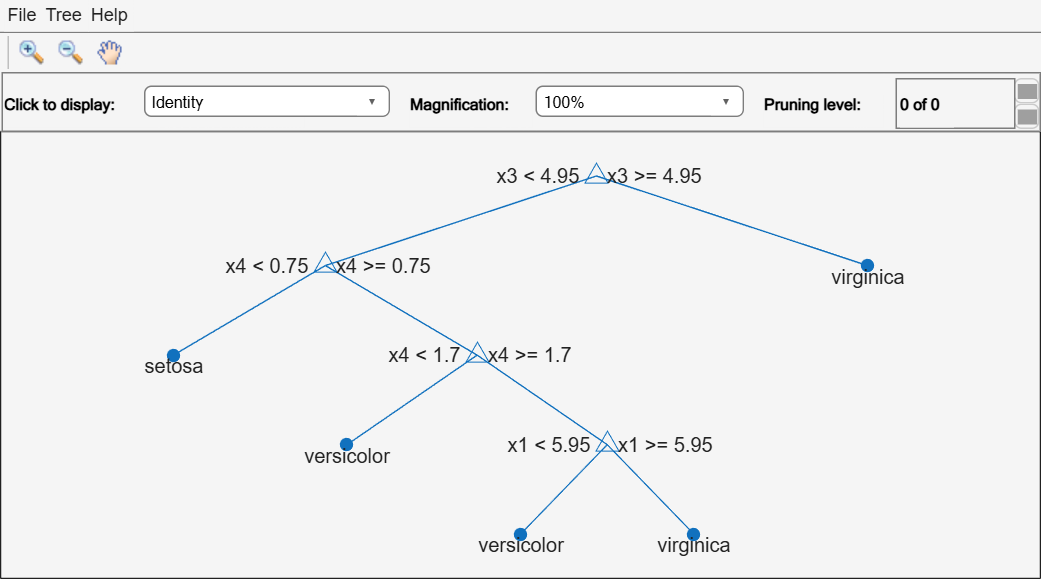

% Ok, the random forest was created, let us check it out...

% 4. Plot one of the decision trees from the random forest graphically
% We inspect the 1st tree in the forest using view(..., 'Mode', 'graph')
figure;
view(rfModel.Trees{1}, 'Mode', 'graph');


% 5. Test the Random Forest with new (test) data
YPred = predict(rfModel, XTest);

% 6. Evaluate accuracy on new data
accuracy = sum(strcmp(YPred, YTest)) / numel(YTest);
fprintf('Random Forest Classification Accuracy on New Data: %.2f%%\n', accuracy * 100);

Random Forest Classification Accuracy on New Data: 93.33%



% Example of classifying a single custom/new observation:
% [sepal length, sepal width, petal length, petal width]
sampleNewData = [5.1, 3.5, 1.4, 0.2]; 
singlePred = predict(rfModel, sampleNewData);
fprintf('Single new data point classified as: %s\n', char(singlePred));

Single new data point classified as: setosa
